# MA 590 : Computational Inverse Problems

# Homework 3

**Note: This live script covers all written and programming responses to parts (a) - (e) of the homework. A written analysis for part (f) is included as well but I decided that it would be more coherent to separate the programming needed for part (f) into a separate script which should also be submitted.**

## Problem 1

(a)

The condition number of $G$ is approximately $4.3948 \times 10^5$. 

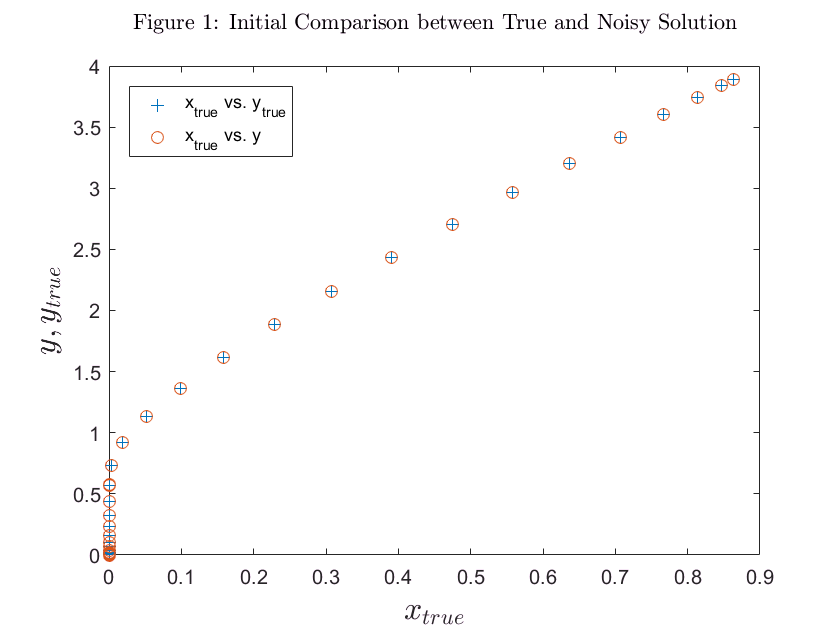

clear all
close all
clc

n = 64;

%The phillips.m function produces Phillips’ test problem, which is a
%discretization of a Fredholm integral equation of the first kind.
[G, y_true, x_true] = phillips(64);

%Note that G is poorly conditioned.
G_condition = cond(G);

%We generate noisy data y.
e = 10^-4*randn(length(y_true),1);
norm_e_test = norm(e);
y = y_true + e; %Noisy data

%Note that the noise does not appear at first to make a large difference.
plot1 = plot(x_true, y_true, '+', x_true, y, 'o');
xlabel('$$x_{true}$$','FontSize',16,'interpreter','latex');
ylabel('$$y, y_{true}$$','FontSize',16,'interpreter','latex'); % make the label look pretty
title({'' 'Figure 1: Initial Comparison between True and Noisy Solution' ''},'Interpreter','latex')
names = {'x_{true} vs. y_{true}' , 'x_{true} vs. y'};
legend(plot1,names, 'location', 'northwest')

(b)

The singular values decrease steadily from the largest singular value $\sigma_1 = 5.8022$  to the smallest singular value $\sigma_{64} = 1.3202 \times 10^{-5}$. We see from the plot that there are no sudden changes in the sizes of the singular values. Although there are 'small' singular values, we see that there are no zero singular values. This conclusion could change if we adopt an alternative definition of zero for this problem along the lines of: "Any singular value less than, say, $10^{-3}$ should be considered 0". In the absence of any definition like this, we take $p = 64$ in the compact SVD for this problem.

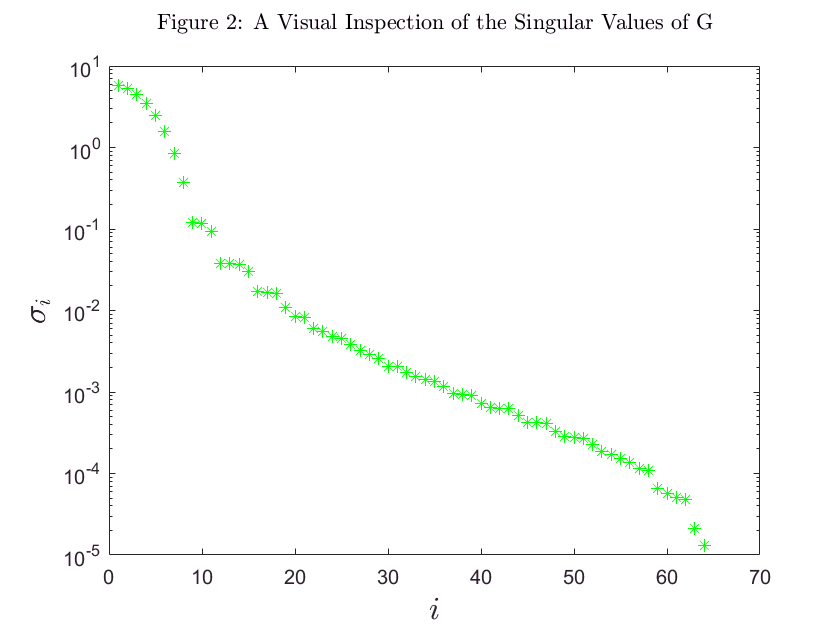

%The full svd of G.
[U,S,V] = svd(G);

%Analyze the singular values of G.
%Note that all singular values are nonzero, although many are 'small'.
singular_values = diag(S);
figure(2)
plot2 = semilogy(1:1:length(singular_values), singular_values, 'g*');
xlabel('$$i$$','FontSize',16,'interpreter','latex');
ylabel('$$\sigma_i$$','FontSize',16,'interpreter','latex'); % make the label look pretty
title({'' 'Figure 2: A Visual Inspection of the Singular Values of G' ''},'Interpreter','latex')

largest_singular_value = max(singular_values);
smallest_singular_value = min(singular_values);

(c)

Using our graph and the Discrete Picard Condition discussed in class, it appears that the DPC does hold in this case because $|u_i^Ty|$ tends to 0 faster than $\sigma_i$ tends to 0 with increasing $i$. However, it's hard to be certain here because of the oscillations we observe in the graph even for indices close to 64. 

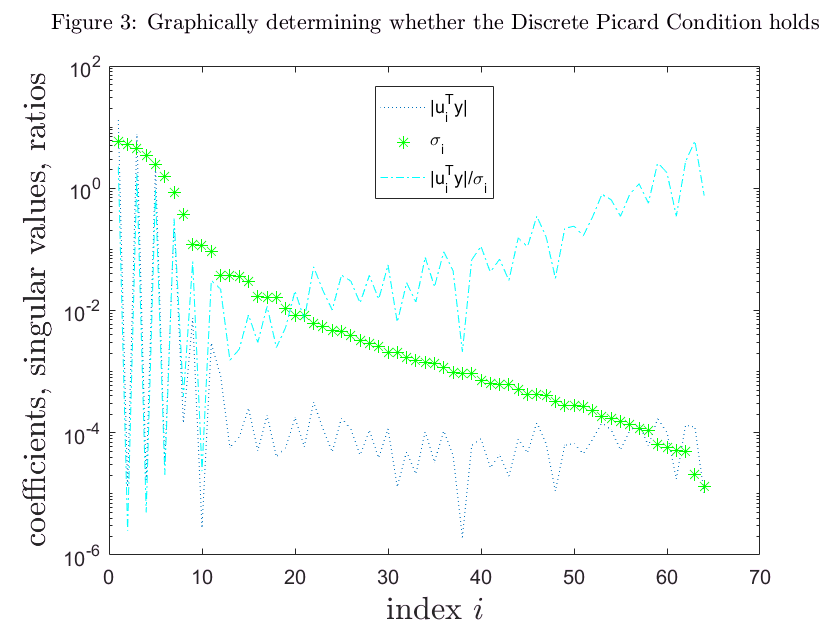

%DPC Holds Here? Look at the svd coefficients.
coefficients = abs(U'*y);
ratios = coefficients ./ singular_values;

figure(3)
plot3 = semilogy(1:64, coefficients,':', 1:64, singular_values, 'g*', 1:64, ratios, 'c-.');
xlabel('index $$i$$','FontSize',16,'interpreter','latex');
ylabel('coefficients, singular values, ratios','FontSize',16,'interpreter','latex'); % make the label look pretty
title({'' 'Figure 3: Graphically determining whether the Discrete Picard Condition holds' ''},'Interpreter','latex')
names = {'|u_i^Ty|' , '\sigma_i', '|u_i^Ty|/\sigma_i'};
legend(plot3,names, 'location', 'north')

(d) 

We define $U_p$, $\Sigma_p$, and $V_p$ to be the matrices used in the compact SVD of $G = U_p\Sigma_pV_p^*$. Only the $p$ column vectors of $U$ and $p$ row vectors of $V^*$ corresponding to the non-zero singular values $\Sigma_p$ are calculated. The remaining vectors of $U$and $V^*$ are not calculated. This is quicker and more economical than the thin SVD if $p$ ≪ *n*. The matrix $U_p$ is thus 64×p, $\Sigma_p$ is p×p diagonal, and $V_p^*$ is *p*×64.

Source: [https://en.wikipedia.org/wiki/Singular_value_decomposition](https://en.wikipedia.org/wiki/Singular_value_decomposition)

Importantly, we note that since we have no zero singular values, $p = 64$.

We find the generalized inverse solution $x^+ = G^+y$, where $G^+ = V_p\Sigma_p^{-1}U_p^*$ is the Moore-Penrose pseudoinverse. Our plot suggests that the generalized inverse solution is not a reasonable approximation of the true solution in thise case since the behavior of the generalized inverse solution varies erratically from the true solution. 

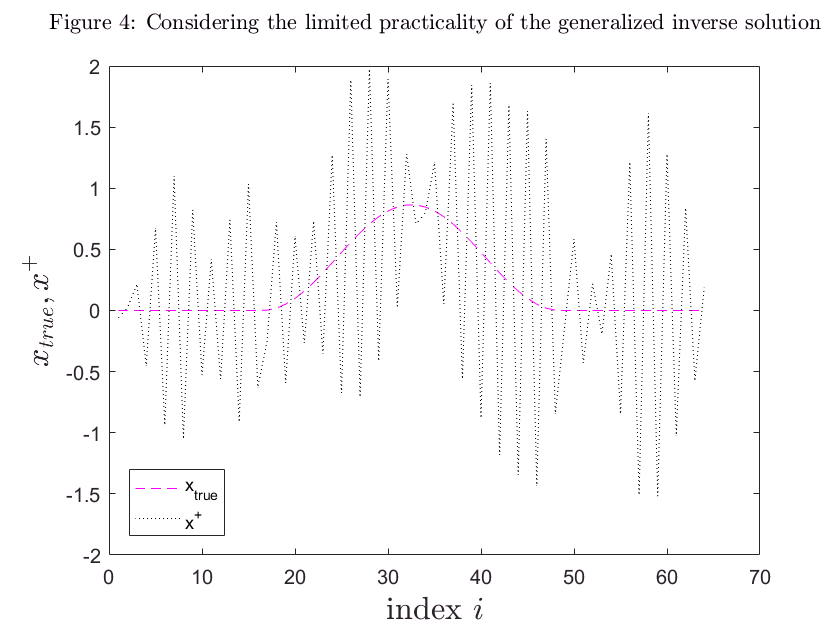

%There are no zero singular values in our case. So p = n. Still we write the
%code to be flexible in case changing earlier steps results in zero
%singular values in future experiments. This means that the compact svd is
%the same as the full svd.
p = n;
nonzero_singular_values = singular_values(1:p);

U_c = U(:,1:p);
S_c = S(1:p,1:p);
V_c = V(:,1:p);

%The pseudoinverse of G.
G_dagger = V_c*inv(S_c)*(U_c)';

%The generalized inverse solution.
x_dagger = G_dagger*y;

figure(4)
plot4 = plot(1:n, x_true, 'm--', 1:n, x_dagger, 'k:');
xlabel('index $$i$$','FontSize',16,'interpreter','latex');
ylabel('$$x_{true}, x^+$$','FontSize',16,'interpreter','latex'); % make the label look pretty
title({'' 'Figure 4: Considering the limited practicality of the generalized inverse solution' ''},'Interpreter','latex')
names = {'x_{true}' , 'x^+'};
legend(plot4,names, 'location', 'southwest')

(e)

Next we find truncated SVD solutions of the form 


$$x_k = V_k\Sigma_k^{-1}U_k^* = \sum_{i = 1}^k \frac{u_i^* y}{\sigma_i} v_i.$$


We see that the 'corner' of the L-curve is at about the point where our vertical axis value is about 3. The 2-norm of $x_k$ first surpasses 3 at about $k=7$. The L-Curve method as we use it is not an exact calculation but a visual method, so the truly optimal parameter may be slightly more or less than 7.

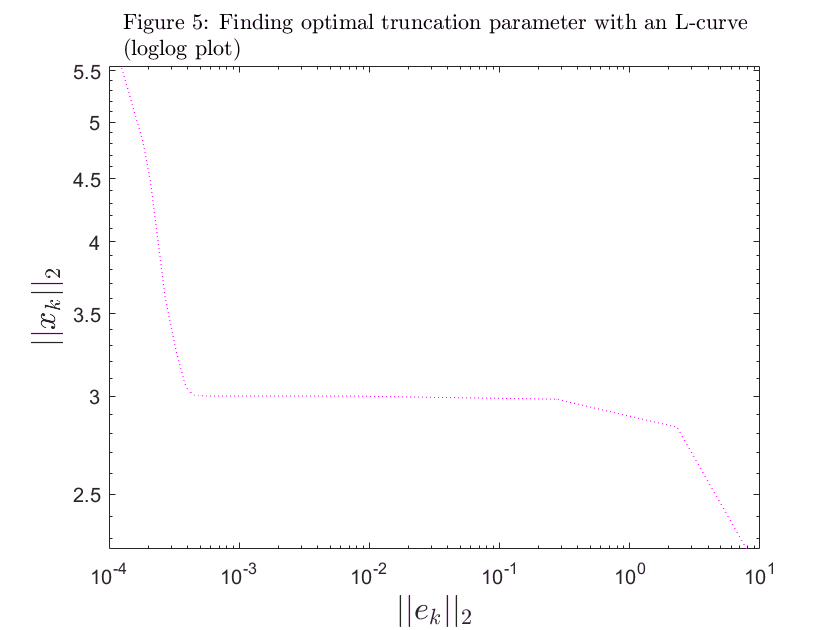

x_k_norms = zeros(1,n);
residual_norms = zeros(1,n);

%Finding approximate solutions using truncated svd. It is simpler to to
%calculate x_k for k=1,...,64 even though we will only inspect k=2,..62.
for ii = 1:n

   x_k =  V(:,1:ii)*inv(S(1:ii,1:ii))*(U(:,1:ii))'*y;
   x_k_norms(ii) = norm(x_k);
   residual_norms(ii) = norm(G*x_k - y);
   
end

%We see that the 'corner' of the L-curve is at about the point where our
%vertical axis value is about 3. The 2-norm of x_k first surpasses 3 at
%about k = 7. The L-Curve method is not an exact calculation but a
%heuristic method, so the truly optimal parameter may be slightly more or
%less than 7.
figure(5)
plot5 = loglog(residual_norms(2:62), x_k_norms(2:62), 'm:');
xlabel('$$||e_k||_2$$','FontSize',16,'interpreter','latex');
ylabel('$$||x_k||_2$$','FontSize',16,'interpreter','latex'); % make the label look pretty
title({'' 'Figure 5: Finding optimal truncation parameter with an L-curve' ''},'Interpreter','latex')

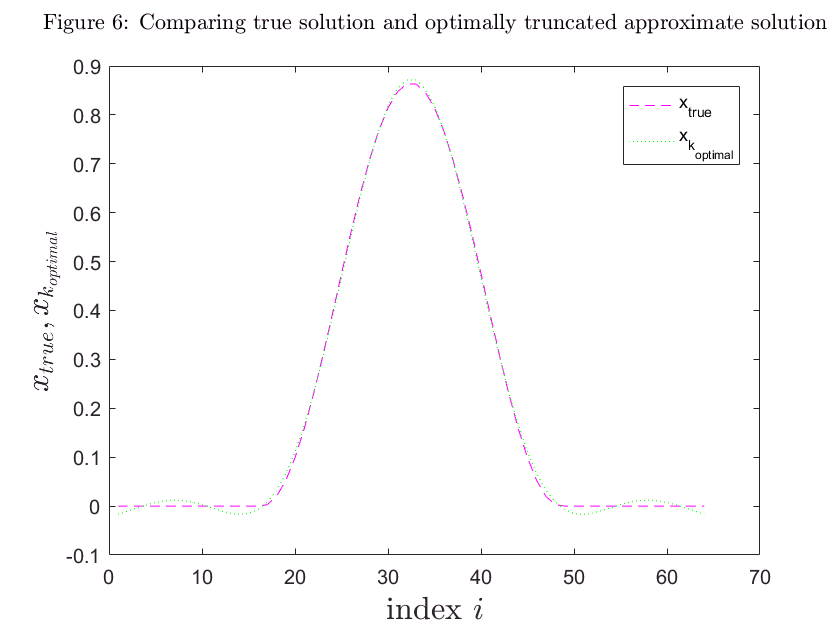


% solution using truncation param k = 7

k_optimal = 7;

x_k_optimal =  V(:,1:k_optimal)*inv(S(1:k_optimal,1:k_optimal))*(U(:,1:k_optimal))'*y;
figure(6)
plot6 = plot(1:n, x_true, 'm--', 1:n, x_k_optimal, 'g:');
xlabel('index $$i$$','FontSize',16,'interpreter','latex');
ylabel('$$x_{true}, x_{k_{optimal}}$$','FontSize',16,'interpreter','latex'); % make the label look pretty
title({'' 'Figure 6: Comparing true solution and optimally truncated approximate solution' ''},'Interpreter','latex')
names = {'x_{true}' , 'x_{k_{optimal}}'};
legend(plot6,names, 'location', 'northeast')

(f)

Increasing the noise and repeating the exercise changes some of our responses to parts (a)-(e) but not others. In summary:

Increased noise will of course cause the difference between $y_{true}$ and $y$ to grow more pronounced since that is precisely what increasing noise means in this problem. Noise does not affect the matrix $G$ and so the singular values of $G$ are unchanged. For the different noise levels we tried, the Discrete Picard Condition appears unchanged and continued to hold as noise increased. The generalized inverse solution becomes increasingly useless as noise increases. The discrepancy between $x^+$ and $x_{true}$ is large enough so that in order to plot the two solutions in the same graph it appears that $x_{true}$ is a constant function, which we know is not the case from our previous work. As noise was increased, using a visual test with our L-curve showed that optimal truncation parameter still corresponded to $k$ such that $||x_k||_2 \approx 3$, so using $k=7$ as the optimal truncation parameter continued to be the best choice as far as our graphical technique could show. Using this truncated SVD solution maintains reasonable approximations of the  true solution as noise increases. Increasing noise does, however, reduce the validity of $x_7$. We should expect this since the truncated solution still relies on a calculation involving the noisy $y$ vector. Observing the results for a noise standard deviation of 1 shows that with this much error the truncated solution may start to become an unreasonable approximation.